% ASK Demodulation.
% You will need an ASK recording, sampling rate  = 2 MSamples/second
% Instructions:
% (1) Set the recording filename 
% (2) Run the script and measure the frequency band of the desired ASK
% transmission
%   

clear;
close all;
filename = 'gqrx_20231113_155401_904406300_2400000_fc.raw' ; %<--- recording
Fs=2000000; %sampling rate
fid = fopen(filename,'rb');
y = fread(fid,'float');
y = y(1:2:end) + 1i*y(2:2:end);
fclose(fid);

 We will use only the I component (real part), since the information will be in the signal envelope for non-coherent detection.

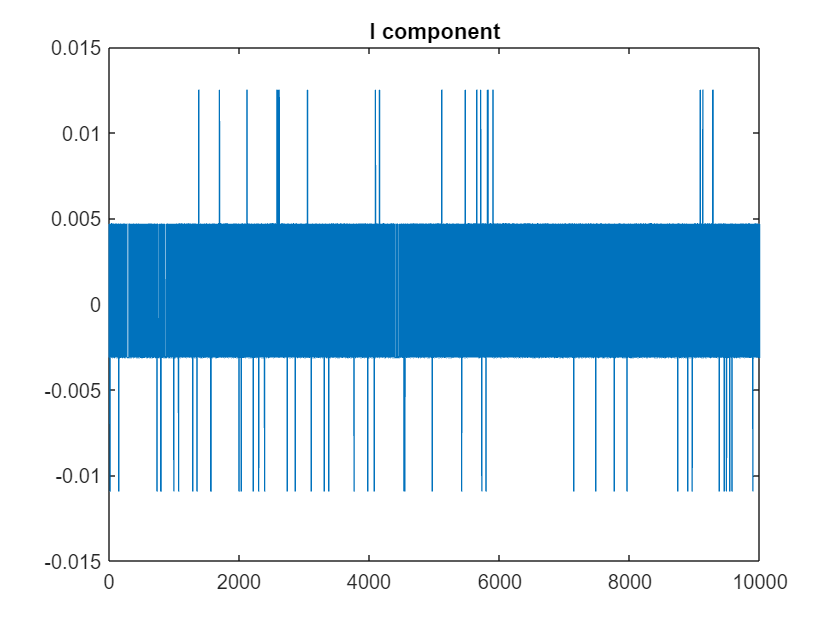

y = real(y);
plot(y(1:10000)) % The y vector has a large number of samples, plot a small subset
title('I component')

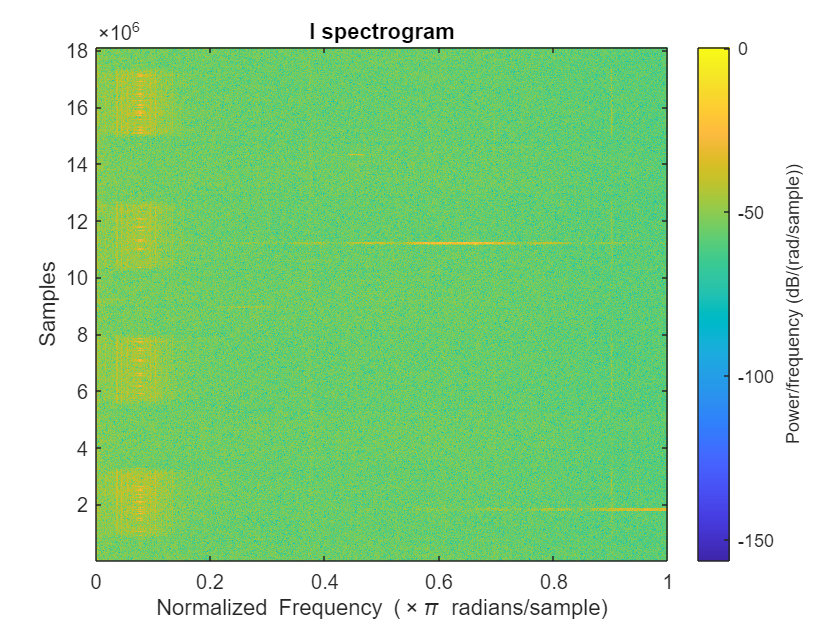

figure
spectrogram(y,10000)
title('I spectrogram')

Plot the above spectrogram in a separate window and zoom in on the desired frequency range. Each SDR will have a different frequency offset due to hardware variations. Example:

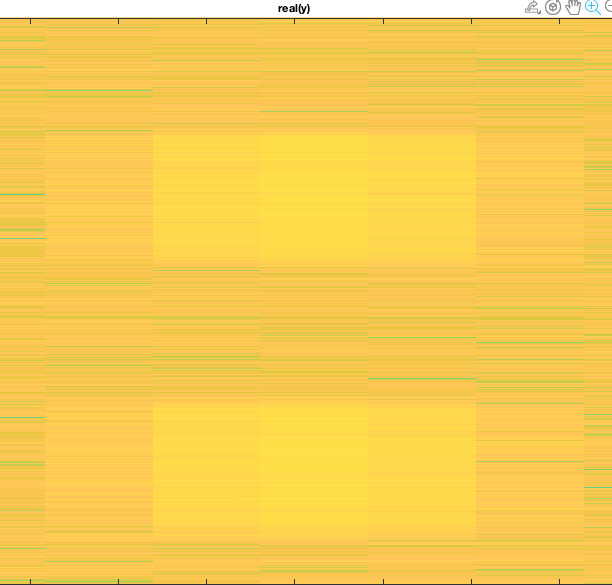

Design a BPF with the Filter Designer tool. 

 Example

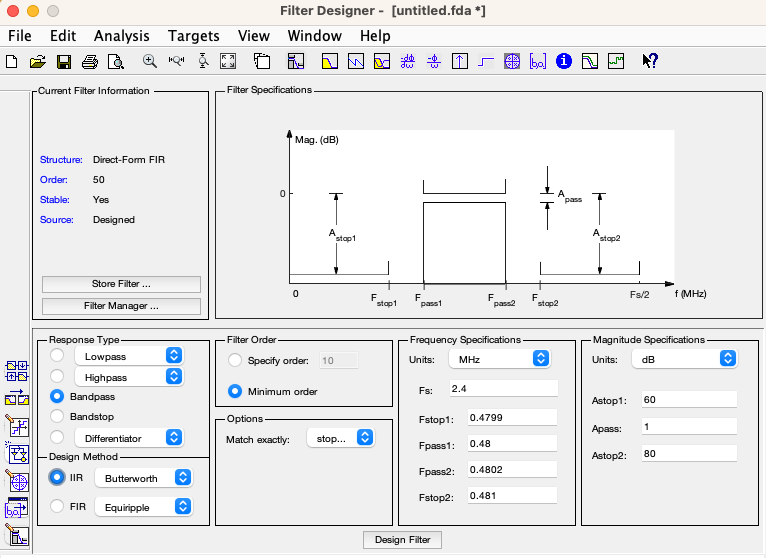

Set the correct frequencies in the Filter Designer tool. Do not use the same frequencies from the above screen capture. The passband (Fpass1, Fpass2) should match exactly with the frequency band of the ASK signal measured in the spectrogram. Fstop1 and Fstop2 should be very close to Fpass1 and Fpass2 (0.001 Mhz difference maximum).

Generate a filter design function, for example name it as bpf.m

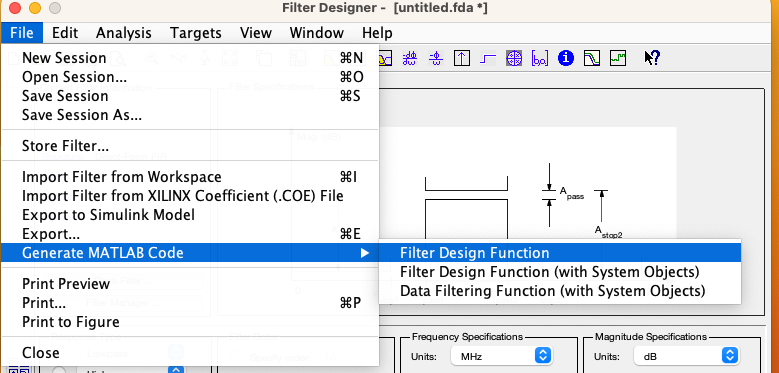

Now,  use the BPF to remove frequency componentes that do not fall in the desired signal band 

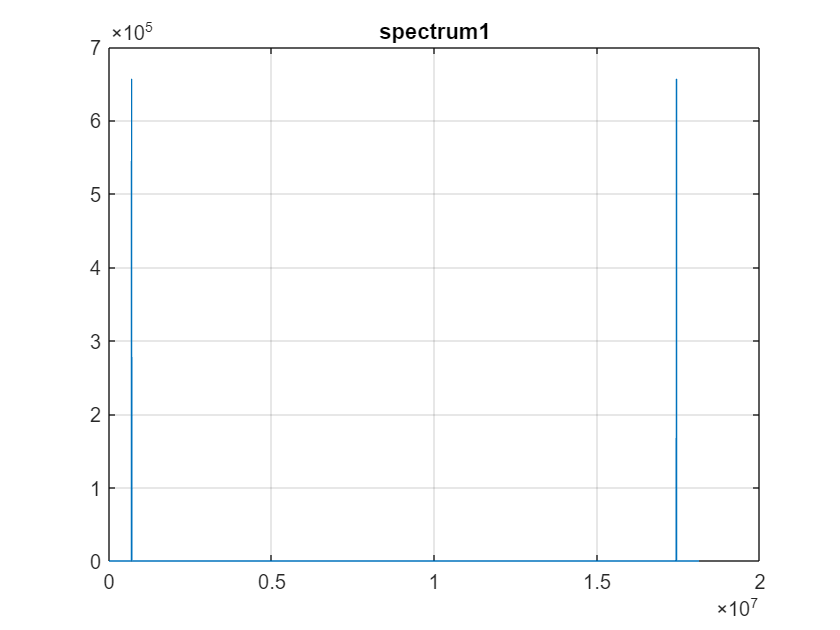

bpfilter = bpf; % IIR butterworth filter built with Filter Designer
yR1= sosfilt(bpfilter.sosMatrix,y); % filter the signal with BPF
yR1 = yR1/max(yR1); % Reduce the amplitude
% %
% % 
plot(abs(fft(yR1)))
title('spectrum1')
grid on;

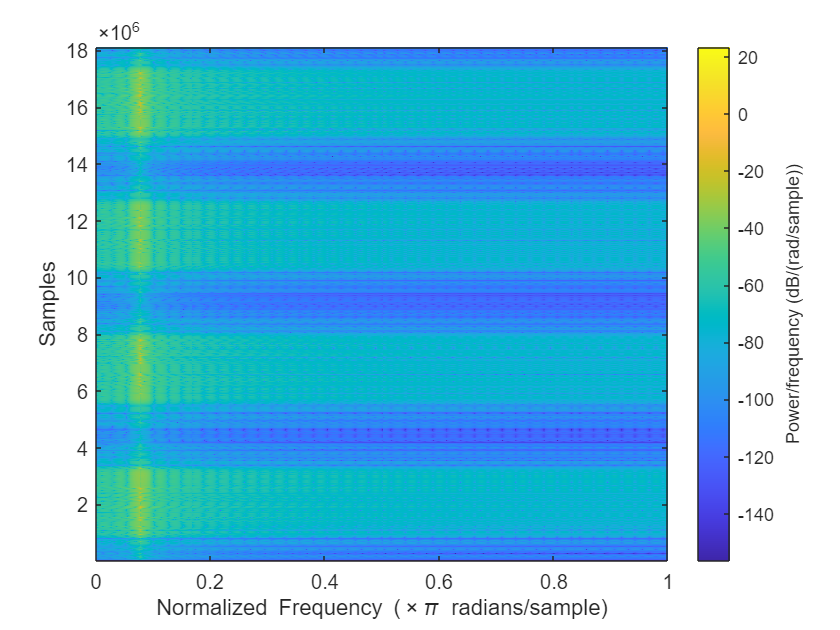

figure 
spectrogram(yR1,10000) % % figure % %

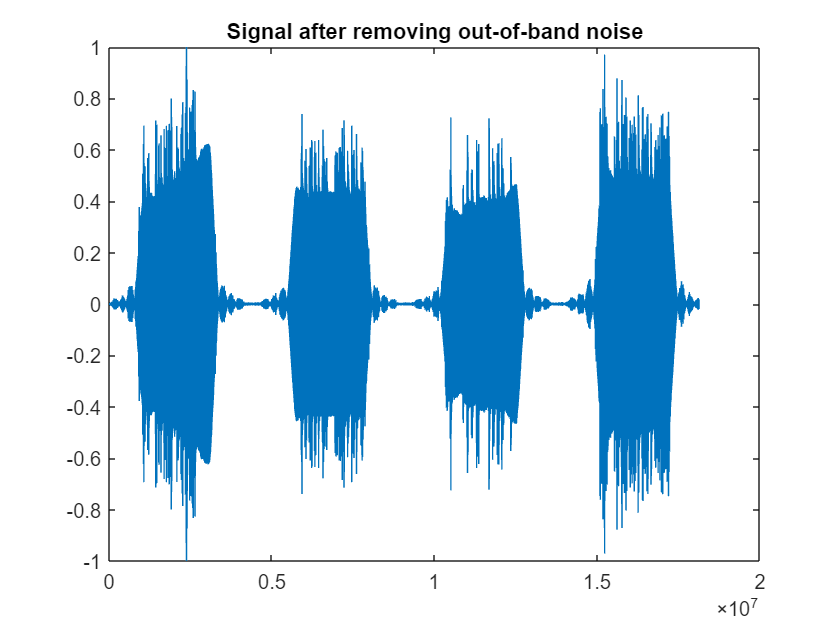

plot(yR1)
title('Signal after removing out-of-band noise')

The information is contained in the envelopes (positive or negative amplitudes). 

We only need one envelope, then will invert the negative amplitudes. 

In addition, we will reduce the sampling rate which is 2 MSamples/second. That is far beyond the needed sampling rate when the data rate is very slow (1 bit per second).

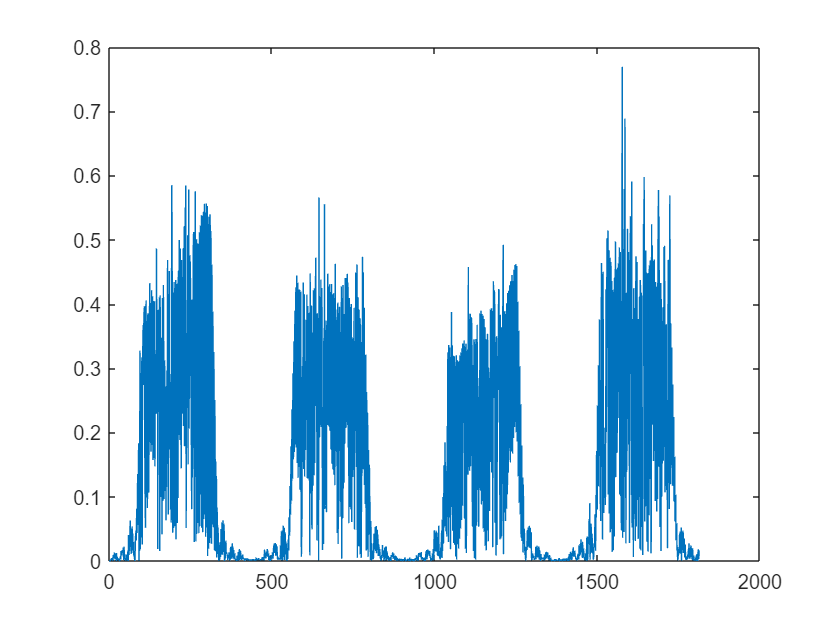

y_positive = abs(yR1(1:10000:end)); %positive amplitudes. Reduce sampling rate by a factor of 10000
plot(y_positive)

We can distinguish the message signal in the envelope. Then we can filter the signal with a LPF to remove the residual noise.

Design a LPF with the Filter Designer tool. Consider that the sampling rate is 2,000,000/10,000 = 200 Hz. Set the cutoff frequency of 10 Hz. You may use an FIR as LPF. 

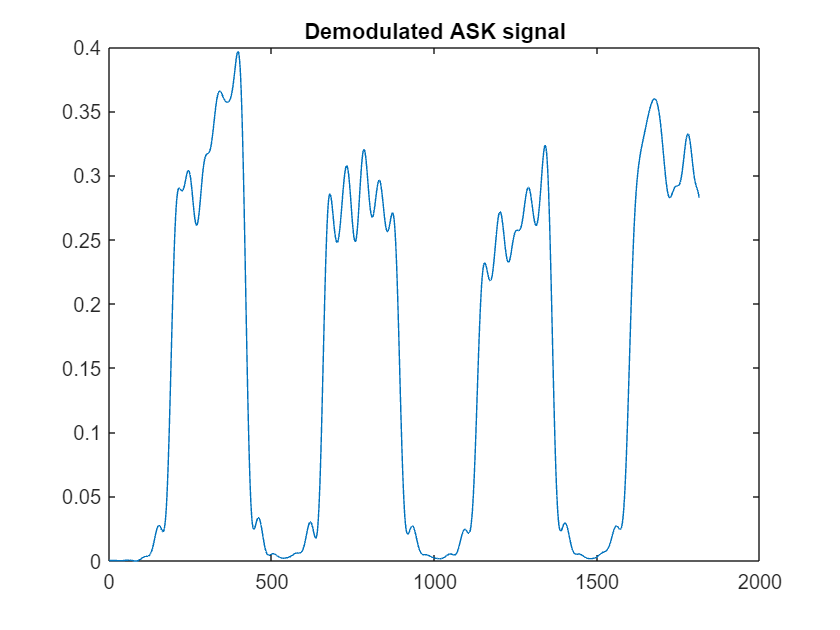

 lpfilter = lpf;
 m = filter(lpfilter.Numerator,1,(y_positive));
 figure
 plot(m)
 title('Demodulated ASK signal')

% 